%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end;

reps = 10;
Qs = [1e4 1e5 1e6 1e7];
Ts = [10e-3 20e-3 30e-3];
taus = logspace(-5, -4, 4);

L_Qs = length(Qs);
L_Ts = length(Ts);
L_taus = length(taus);

num_runs = reps * L_Qs * L_Ts * L_taus 

% Q=1e5 T=10e-3 tau=2e-4 locks
% Q=1e5 T=30e-3 tau=5e-4 locks

rmss = zeros(reps, L_Qs, L_Ts, L_taus);
linspace_rms = zeros(reps, L_Qs);

R = @(Q, df, f_res_o) 1 ./ (1 + 4*Q^2 * df.^2 ./ f_res_o.^2 );

parfor l = 1 : reps
    %% generate signal and noise
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q);
    noise = generate_thermal_noise(t);

    for j = 1 : L_Qs
        Q_orig = Qs(j)
        Q = Q_orig / heterodyning_ratio;
        
        bandwidth = f_a / Q; % or f_a_original / Q_orig
        limiting_band = [f_a-bandwidth, f_a+bandwidth];
        
        linspace_gives_rms = rms(f_axion - linspace(limiting_band(1), limiting_band(2), length(t)));
        linspace_rms(l, j) = linspace_gives_rms;
        
        signal_Qed = signal * sqrt(Q_orig);
        
        for k = 1 : L_Ts
            T = Ts(k)
            
            noise_power = calculate_noise_power(f_sampling, T);
            noise_Ted = noise * sqrt(noise_power);
            
            for m = 1 : L_taus
                tau_iwave = taus(m)
                f_guess = f_a;
    
                STATE_PS = iwave_setup(f_sampling, tau_iwave, f_guess, 0);
                state_res = resonator_setup();
                f_iwave = zeros(size(t));
                ys = zeros(size(t));
                xs = zeros(size(t));
                f_0_current = f_a + bandwidth/4; % starting guess
                
                for i = 1 : length(t)
                    x = signal_Qed(i) + noise_Ted(i);
                    x = x * sqrt(R(Q_orig, f_axion(i) - f_0_current, f_0_current + heterodyning_shift));
                    [state_res, y] = resonator_step2(state_res, x, f_0_current, bandwidth, f_sampling);
                    [STATE_PS, pdout, pqout, paout, peout, pfout, pfstateout] = iwave_step(STATE_PS, y);
                    f_0_current = pfout;
                    if f_0_current > limiting_band(2)
                        f_0_current = limiting_band(2);
                    elseif f_0_current < limiting_band(1)
                        f_0_current = limiting_band(1);
                    end
                    f_iwave(i) = f_0_current;
                    ys(i) = y;
                    xs(i) = x;
                end
    
                % front to chop off
                start_secs = 0.0015;
                assert(start_secs < t(end)/3);
                start = round(start_secs * f_sampling);
                the_rms = rms(f_iwave(start:end) - f_axion(start:end))
                
                rmss(l, j, k, m) = the_rms;
                
                figure
                plot(t, f_axion - f_a)
                hold on
                plot(t, f_iwave - f_a)
            end
        end
    end
end

avg_rmss = mean(rmss, 1);
std_rmss = std(rmss, 1);
avg_std = mean(std_rmss, 'all')

avg_std = 1.4801e+03


avg_lins_rms = mean(linspace_rms, 1);

best_taus = zeros(L_Qs, L_Ts);

for j = 1 : L_Qs
    Q_orig = Qs(j);
    lins_rms = avg_lins_rms(1, j);
    
    for k = 1 : L_Ts
        T = Ts(k);
        
        [min_rms, min_index] = min(rmss(1,j,k,:));
        min_rms;
        best_taus(j, k) = taus(min_index);
        
        for m = 1 : L_taus
            %tau = taus(m)
            %avg_rmss(1, j, k, m)
        end
    end
end

best_taus

best_taus = 	1.0e+-4 *

    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000
    0.4642    0.4642    0.4642
    0.1000    0.1000    0.1000


Q_orig = 10000

T = 0.0100

the_rms = 7.1675e+03

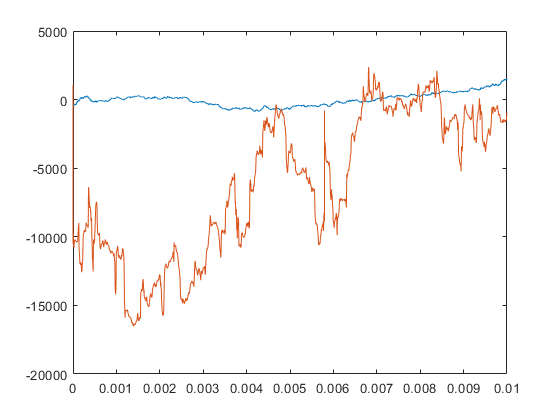

T = 0.0200

the_rms = 2.8472e+04

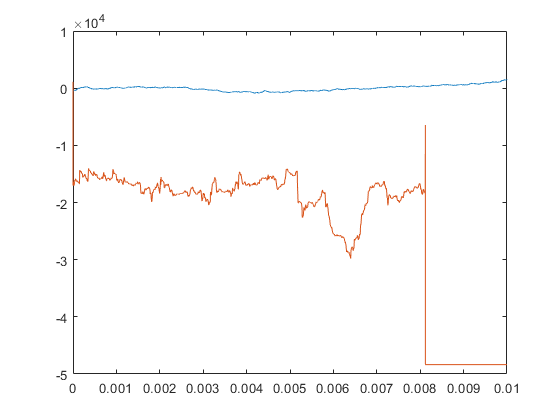

T = 0.0300

the_rms = 8.9518e+03

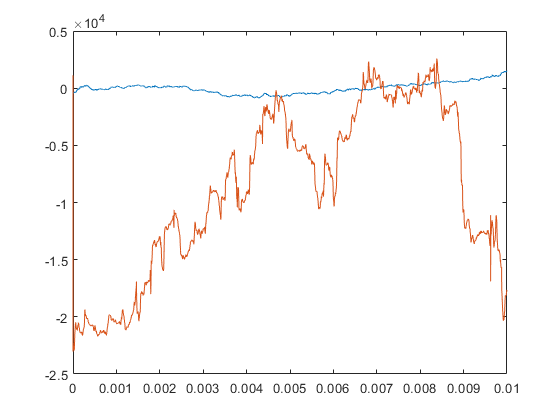

Q_orig = 100000

T = 0.0100

the_rms = 619.8071

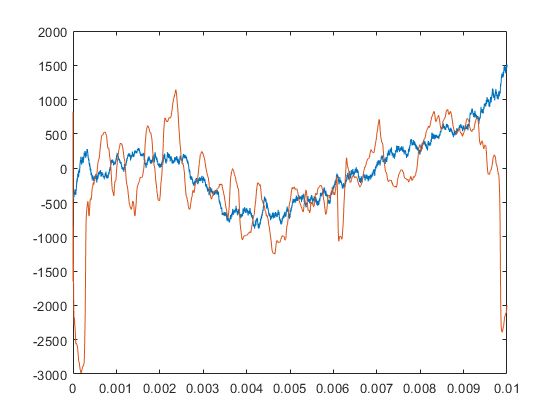

T = 0.0200

the_rms = 1.6453e+03

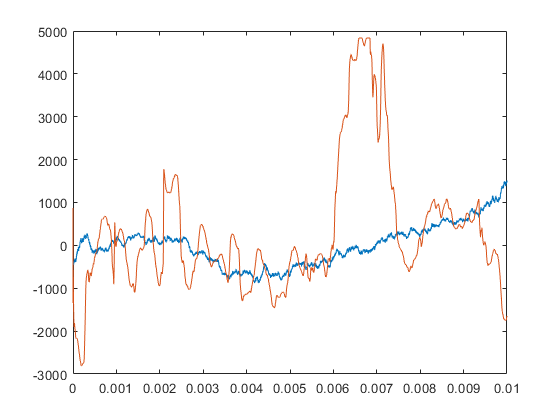

T = 0.0300

the_rms = 2.4744e+03

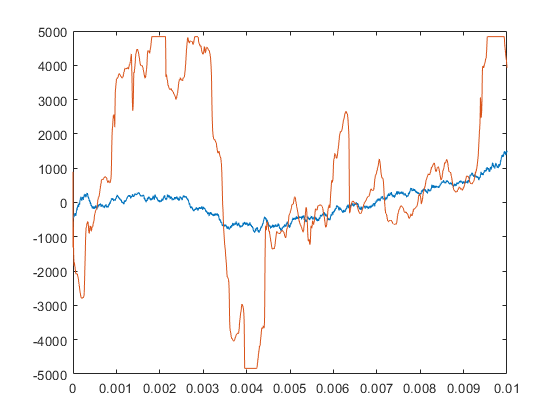

Q_orig = 1000000

T = 0.0100

the_rms = 251.1588

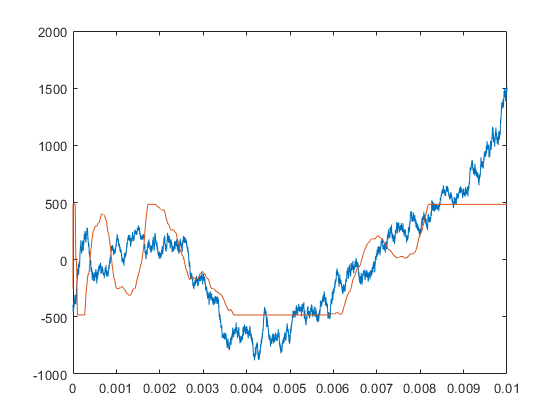

T = 0.0200

the_rms = 272.8884

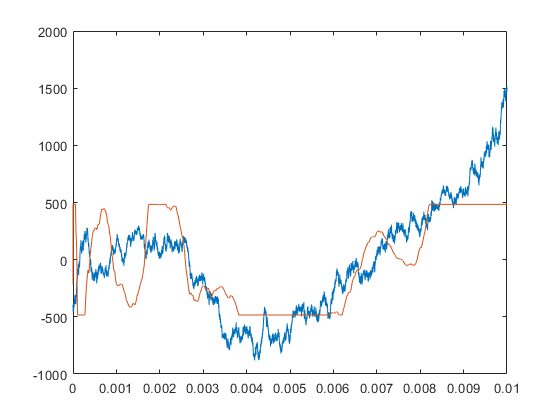

T = 0.0300

the_rms = 283.0026

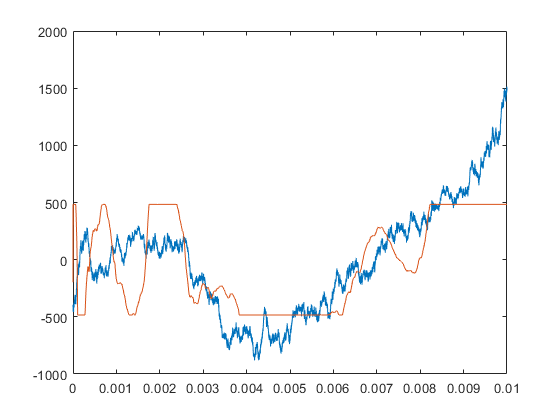

Q_orig = 10000000

T = 0.0100

the_rms = 523.1703

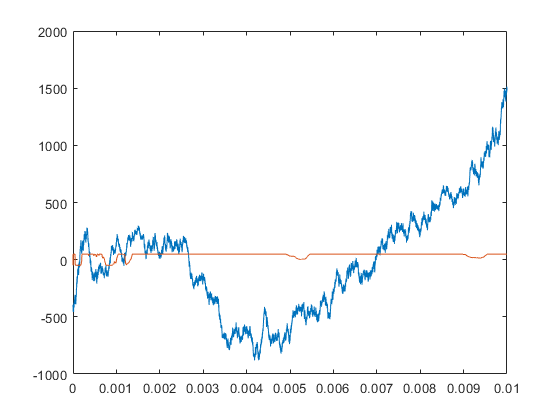

T = 0.0200

the_rms = 523.2240

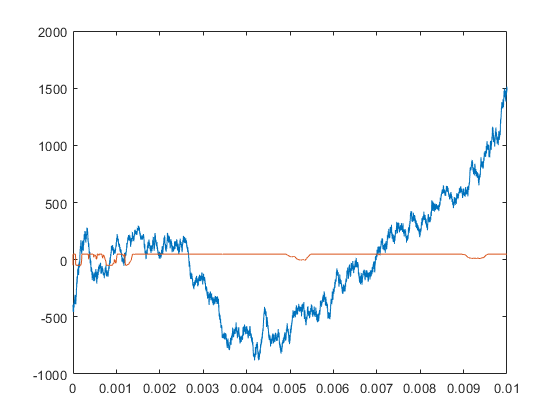

T = 0.0300

the_rms = 523.3008

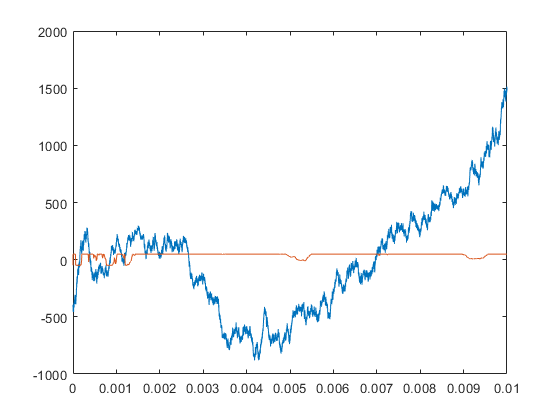

%{
f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q);
noise = generate_thermal_noise(t);

for j = 1 : L_Qs
    Q_orig = Qs(j)
    Q = Q_orig / heterodyning_ratio;
    
    bandwidth = f_a / Q; % or f_a_original / Q_orig
    limiting_band = [f_a-bandwidth, f_a+bandwidth];
    
    linspace_gives_rms = rms(f_axion - linspace(limiting_band(1), limiting_band(2), length(t)));
    linspace_rms(l, j) = linspace_gives_rms;
    
    signal_Qed = signal * sqrt(Q_orig);
    
    for k = 1 : L_Ts
        T = Ts(k)
        
        noise_power = calculate_noise_power(f_sampling, T);
        noise_Ted = noise * sqrt(noise_power);
        
        tau_iwave = best_taus(j, k);
        f_guess = f_a;

        STATE_PS = iwave_setup(f_sampling, tau_iwave, f_guess, 0);
        state_res = resonator_setup();
        f_iwave = zeros(size(t));
        ys = zeros(size(t));
        xs = zeros(size(t));
        f_0_current = f_a + bandwidth/4; % starting guess
        
        for i = 1 : length(t)
            x = signal_Qed(i) + noise_Ted(i);
            x = x * sqrt(R(Q_orig, f_axion(i) - f_0_current, f_0_current + heterodyning_shift));
            [state_res, y] = resonator_step2(state_res, x, f_0_current, bandwidth, f_sampling);
            [STATE_PS, pdout, pqout, paout, peout, pfout, pfstateout] = iwave_step(STATE_PS, y);
            f_0_current = pfout;
            if f_0_current > limiting_band(2)
                f_0_current = limiting_band(2);
            elseif f_0_current < limiting_band(1)
                f_0_current = limiting_band(1);
            end
            f_iwave(i) = f_0_current;
            ys(i) = y;
            xs(i) = x;
        end

        % front to chop off
        start_secs = 0.0015;
        assert(start_secs < t(end)/3);
        start = round(start_secs * f_sampling);
        the_rms = rms(f_iwave(start:end) - f_axion(start:end))
        
        rmss(l, j, k, m) = the_rms;
        
        figure
        plot(t, f_axion - f_a)
        hold on
        plot(t, f_iwave - f_a)
    end
end

%}